# Final Project Writeup

## Trial by Trial Variability

We will compute the Fano Factor as a function of time aligned to both the target appearance, movement onset, and go-cue separately for curved and straight reaches to determine how variability evolves across delay and movement and whether this differs for the reach types, considering curved reaches are arguably more complex.

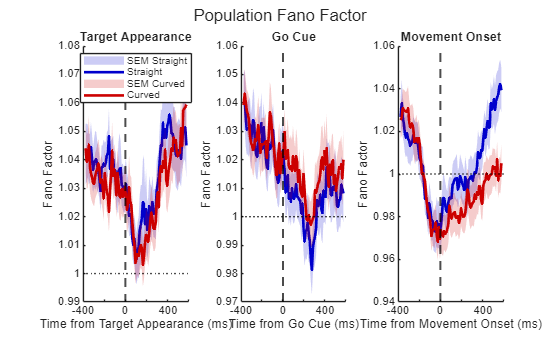

% We will compute the Fano Factor as a function of time aligned to both the 
% target appearance, movement onset, and go-cue separately for curved and straight 
% reaches to determine how variability evolves across delay and movement 
% and whether this differs for the reach types, considering curved reaches 
% are arguably more complex.

conditionIDs = [R.conditionID];
straight_idx = mod(conditionIDs, 3) == 1;
curved_idx = mod(conditionIDs, 3) == 2;

straight_trials = find(straight_idx);
curved_trials   = find(curved_idx);

bin_size = 50;
step_size = 10;
pre_window = 400;
post_window = 600;

bin_centers = (-pre_window + bin_size/2) : step_size : (post_window - bin_size/2);
num_bins = numel(bin_centers);
num_units = numel(R(1).unit);

target_align = [R.targetAppearsTime];
gocue_align = [R.goCueTime];
onset_align = [R.moveOnsetTime];

straight_dir_ids = floor(conditionIDs(straight_idx) / 3); 
curved_dir_ids = floor(conditionIDs(curved_idx) / 3);

unique_straight_dirs = unique(straight_dir_ids);
unique_curved_dirs = unique(curved_dir_ids);

ff_target = nan(num_units, num_bins, 2);
ff_gocue = nan(num_units, num_bins, 2);
ff_onset = nan(num_units, num_bins, 2);

for unit = 1:num_units
    for cond = 1:2
        if cond == 1
            trial_ids = straight_trials;
            dir_ids = straight_dir_ids;
            unique_dirs = unique_straight_dirs;
        else
            trial_ids = curved_trials;
            dir_ids = curved_dir_ids;
            unique_dirs = unique_curved_dirs;
        end

        num_dirs = numel(unique_dirs);

        ff_target_by_dir = nan(num_dirs, num_bins);
        ff_gocue_by_dir = nan(num_dirs, num_bins);
        ff_onset_by_dir = nan(num_dirs, num_bins);

        for d = 1:num_dirs
            dir_mask = dir_ids == unique_dirs(d);
            dir_trial_ids = trial_ids(dir_mask); 
            num_dir_trials = numel(dir_trial_ids);

            counts_target = nan(num_dir_trials, num_bins);
            counts_gocue = nan(num_dir_trials, num_bins);
            counts_onset = nan(num_dir_trials, num_bins);

            for trial = 1:num_dir_trials
                tr = dir_trial_ids(trial);
                spike_times = R(tr).unit(unit).spikeTimes;

                rel_target = spike_times - target_align(tr);
                rel_gocue = spike_times - gocue_align(tr);
                rel_onset = spike_times - onset_align(tr);

                for b = 1:num_bins
                    t_lo = bin_centers(b) - bin_size/2;
                    t_hi = bin_centers(b) + bin_size/2;

                    counts_target(trial, b) = sum(rel_target >= t_lo & rel_target < t_hi);
                    counts_gocue( trial, b) = sum(rel_gocue  >= t_lo & rel_gocue  < t_hi);
                    counts_onset( trial, b) = sum(rel_onset  >= t_lo & rel_onset  < t_hi);
                end
            end

            ff_target_by_dir(d, :) = compute_fano_factor(counts_target);
            ff_gocue_by_dir( d, :) = compute_fano_factor(counts_gocue);
            ff_onset_by_dir( d, :) = compute_fano_factor(counts_onset);
        end

        ff_target(unit, :, cond) = nanmean(ff_target_by_dir, 1);
        ff_gocue( unit, :, cond) = nanmean(ff_gocue_by_dir,  1);
        ff_onset( unit, :, cond) = nanmean(ff_onset_by_dir,  1);
    end
end

mean_ff = @(ff, cond) nanmean(ff(:, :, cond), 1);
sem_ff = @(ff, cond) nanstd(ff(:, :, cond), 0, 1) / sqrt(sum(~all(isnan(ff(:,:,cond)), 2)));

%Plotting
colors = struct('straight', [0 0 0.8], 'curved', [0.8 0 0]);
align_labels = {'Target Appearance', 'Go Cue', 'Movement Onset'};
x_labels = {'Time from Target Appearance (ms)', ...
                 'Time from Go Cue (ms)', ...
                 'Time from Movement Onset (ms)'};
ff_all = {ff_target, ff_gocue, ff_onset};

figure;

for a = 1:3
    subplot(1, 3, a);
    hold on;
    ff = ff_all{a};
    for cond = 1:2
        m  = mean_ff(ff, cond);
        sem = sem_ff(ff, cond);
        if cond == 1
            col = colors.straight;
            lbl = 'Straight';
            fill_lbl = 'SEM Straight';
        else
            col = colors.curved;
            lbl = 'Curved';
            fill_lbl = 'SEM Curved';
        end
        fill([bin_centers, fliplr(bin_centers)], ...
             [m + sem, fliplr(m - sem)], ...
             col, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', fill_lbl);
        plot(bin_centers, m, '-', 'Color', col, 'LineWidth', 2, 'DisplayName', lbl);
    end
    xline(0, 'k--', 'LineWidth', 1.5, 'HandleVisibility', 'off');
    yline(1, 'k:',  'LineWidth', 1.0, 'HandleVisibility', 'off');

    xlabel(x_labels{a});
    ylabel('Fano Factor');
    title(align_labels{a});
    xlim([-pre_window, post_window]);
    if a == 1
        legend('Location', 'best');
    end
end
sgtitle('Population Fano Factor');

High level method:

- Trials are split into straight vs curved

- Trials are grouped by reach direction (36 conditions as indicated by the dataset)

- Spike counts are binned in 50ms windows, stepped every 10ms. The window of interest is 400ms before to 600ms after each alignment event (target appearance, go cue, and movement onset)

- For each direction group, FF is computed per bin per unit, then averaged across directions, then averaged across all units

As we learned in class, the Fano Factor (FF) is used to quantify neural variability, with FF=1 indicating regular firing. The plot shown was averaged At target appearance, the variabilty drops, and steadily rises. The same pattern is shown in the go cue alignment plot. Interestingly, the curved reaches have a slightly higher variability throughout this plot, although the difference is minimal. This could be because the curved reaches are more complex than the straight reaches, and less stereotyped after instruction. Different curved trials may involve differeny movement strategies during this planning phase initiated by the go cue. It also might indicate that straight reaches are more stereotyped after the appearance of the go-cue. When aligned to the movement onset, we see the opposite pattern. The straight reaches have a higher variability after movement onset compared to the curved reaches. This could mean that at movement onset, the curved trajectories execute movement in a stereotyped way. These results suggest that straight reaches are more locked to instruction, and curved reaches are more locked to execution. However, it is important to note that these differences in variability are minor. In addition, averaging over the population might minimize the differences in variability we see between the two conditions. 

## NOTE: Put in FF between arrays and single units

## Linear Dimensionality Reduction

We will do cross-validated PCA on M1 activity to determine the true low dimensional structure of the neuron's responses, comparing dimensionality under no normalization, z-scoring, and soft normalization.

conditionIDs = [R.conditionID];
straight_idx = mod(conditionIDs, 3) == 1;
curved_idx = mod(conditionIDs, 3) == 2;
straight_trials = find(straight_idx);
curved_trials = find(curved_idx);

% window will change in the next PCA trajectory analysis this is just for
pre_window = 150;
post_window = 50;
bin_size = 20;
time_bins = -pre_window : bin_size : post_window;
bin_centers = time_bins(1:end-1) + bin_size/2;
n_bins = numel(bin_centers);
n_units = numel(R(1).unit);

onset_align = [R.moveOnsetTime];
all_trials = [straight_trials(:); curved_trials(:)];
n_trials = numel(all_trials);

firing_rates = nan(n_trials, n_units, n_bins);
for t = 1:n_trials
    tr = all_trials(t);
    t0 = onset_align(tr);
    for u = 1:n_units
        spike_times = R(tr).unit(u).spikeTimes - t0;
        counts = histcounts(spike_times, time_bins);
        firing_rates(t, u, :) = counts / (bin_size / 1000);
    end
end
disp('Firing rates created.')

Firing rates created.


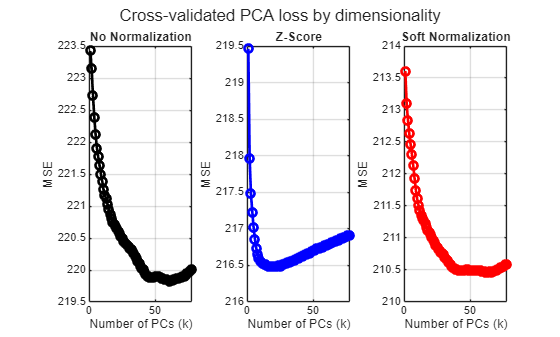


fr_straight = squeeze(mean(firing_rates(1:numel(straight_trials), :, :), 1));  % [n_units x n_bins]
fr_curved   = squeeze(mean(firing_rates(numel(straight_trials)+1:end, :, :), 1));
fr_cond_avg = permute(cat(3, fr_straight', fr_curved'), [3 1 2]);  % [2 x n_bins x n_units]
n_conds = 2;

k = 5;
soft_norm = 5;
methods = {'none', 'zscore', 'soft'};
normalization_labels = {'No Normalization', 'Z-Score', 'Soft Normalization'};
colors_method = [0 0 0; 0 0 1; 1 0 0];

n_straight = numel(straight_trials);
n_curved = numel(curved_trials);
cond_labels = [ones(n_straight, 1); 2*ones(n_curved, 1)];

fold_ids_trials = zeros(n_trials, 1);
for cond = 1:2
    cond_mask = find(cond_labels == cond);
    n_cond = numel(cond_mask);
    perm = randperm(n_cond);
    cond_folds = mod(0:n_cond-1, k) + 1;
    fold_ids_trials(cond_mask) = cond_folds(perm);
end

n_X_fixed = floor(n_units / 2);
max_dims = n_X_fixed - 1;

cv_loss = nan(numel(methods), k, k, max_dims);
n_plot_dims = min(n_X_fixed - 1, 2*n_bins - 1);
all_explained = nan(numel(methods), n_plot_dims);
all_score = cell(numel(methods), 1);
all_coeff = cell(numel(methods), 1);

for m = 1:numel(methods)

    for fold_r = 1:k
        train_idx = find(fold_ids_trials ~= fold_r);
        test_idx = find(fold_ids_trials == fold_r);
        n_train = numel(train_idx);
        n_test = numel(test_idx);

        for fold_c = 1:k
            neuron_perm = randperm(n_units);
            x_neurons = neuron_perm(1:n_X_fixed);
            y_neurons = neuron_perm(n_X_fixed+1:end);
            n_Y = numel(y_neurons);

            X_train = reshape(permute(firing_rates(train_idx, x_neurons, :), [1 3 2]), n_train*n_bins, n_X_fixed);
            Y_train = reshape(permute(firing_rates(train_idx, y_neurons, :), [1 3 2]), n_train*n_bins, n_Y);
            X_test = reshape(permute(firing_rates(test_idx,  x_neurons, :), [1 3 2]), n_test*n_bins,  n_X_fixed);
            Y_test = reshape(permute(firing_rates(test_idx,  y_neurons, :), [1 3 2]), n_test*n_bins,  n_Y);

            switch methods{m}
                case 'none'
                    X_train_n = X_train; X_test_n = X_test;
                case 'zscore'
                    mu_x = mean(X_train, 1);
                    sig_x = std(X_train, 0, 1); sig_x(sig_x==0) = 1;
                    X_train_n = (X_train - mu_x) ./ sig_x;
                    X_test_n  = (X_test  - mu_x) ./ sig_x;
                case 'soft'
                    rng_x = max(X_train,[],1) - min(X_train,[],1);
                    X_train_n = X_train ./ (rng_x + soft_norm);
                    X_test_n  = X_test  ./ (rng_x + soft_norm);
            end

            mu_X = mean(X_train_n, 1);
            X_train_c = X_train_n - mu_X;
            X_test_c = X_test_n  - mu_X;
            mu_Y = mean(Y_train, 1);
            Y_train_c = Y_train - mu_Y;

            [coeff, score, ~] = pca(X_train_c, 'NumComponents', max_dims);

            for d = 1:max_dims
                S_train = score(:, 1:d);
                beta = S_train \ Y_train_c;
                S_test = X_test_c * coeff(:, 1:d);
                Y_hat = S_test * beta + mu_Y;
                cv_loss(m, fold_r, fold_c, d) = mean((Y_test - Y_hat).^2, 'all');
            end
        end
    end

    X_plot = reshape(fr_cond_avg(:, :, :), n_conds*n_bins, n_units);
    FR_all = reshape(permute(firing_rates, [1 3 2]), n_trials*n_bins, n_units);
    
    switch methods{m}
        case 'none'
            FR_all_n = FR_all;
        case 'zscore'
            mu_x = mean(FR_all, 1);
            sig_x = std(FR_all, 0, 1); sig_x(sig_x==0) = 1;
            FR_all_n = (FR_all - mu_x) ./ sig_x;
        case 'soft'
            rng_x = max(FR_all,[],1) - min(FR_all,[],1);
            FR_all_n = FR_all ./ (rng_x + soft_norm);
    end
    
    FR_all_n = reshape(FR_all_n, n_trials, n_bins, n_units);
    psth_s = squeeze(mean(FR_all_n(1:n_straight, :, :), 1)); 
    psth_c = squeeze(mean(FR_all_n(n_straight+1:end, :, :), 1));
    X_plot_final = [psth_s; psth_c];
    X_plot_final = X_plot_final - mean(X_plot_final, 1);
    
    [coeff_full, score_full, ~, ~, explained] = pca(X_plot_final);
    all_score{m} = score_full;  
    all_explained(m, :) = explained(1:n_plot_dims)';
    all_score{m} = score_full;
    all_coeff{m} = coeff_full;
end

mean_loss = squeeze(mean(cv_loss, [2 3]));

% CV loss plot
figure;
for m = 1:numel(methods)
    subplot(1, 3, m);
    plot(1:max_dims, mean_loss(m, :), '-o', 'Color', colors_method(m,:), 'LineWidth', 2);
    xlabel('Number of PCs (k)');
    ylabel('MSE');
    title(normalization_labels{m});
    grid on;
end
sgtitle('Cross-validated PCA loss by dimensionality');

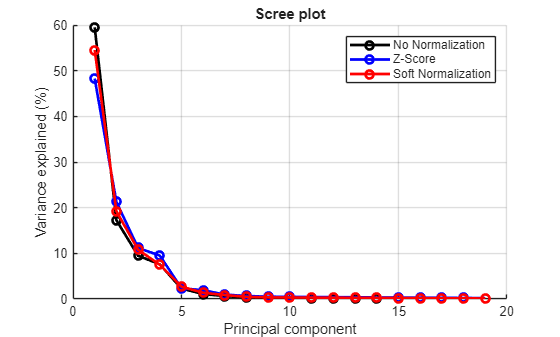


% Scree plot
n_plot = min(20, n_plot_dims);
figure; hold on;
for m = 1:numel(methods)
    plot(1:n_plot, all_explained(m, 1:n_plot), '-o', 'Color', colors_method(m,:), 'LineWidth', 2);
end
xlabel('Principal component');
ylabel('Variance explained (%)');
title('Scree plot');
legend(normalization_labels, 'Location', 'northeast');
grid on;

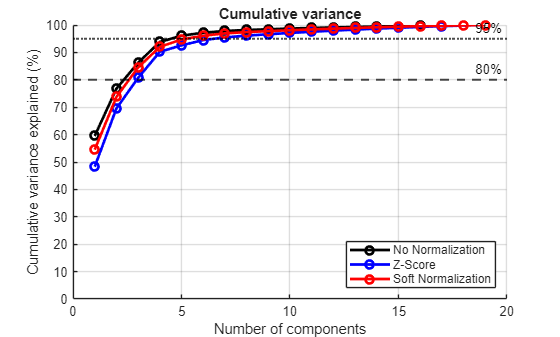


% Cumulative variance
figure; hold on;
for m = 1:numel(methods)
    cum_exp = cumsum(all_explained(m, :));
    plot(1:n_plot, cum_exp(1:n_plot), '-o', 'Color', colors_method(m,:), 'LineWidth', 2);
end
yline(80, 'k--', 'LineWidth', 1.5, 'Label', '80%');
yline(95, 'k:',  'LineWidth', 1.5, 'Label', '95%');
xlabel('Number of components');
ylabel('Cumulative variance explained (%)');
title('Cumulative variance');
ylim([0 100]);
legend(normalization_labels, 'Location', 'southeast');
grid on;

## PCA Trajectory Plots

conditionIDs = [R.conditionID];
straight_idx = mod(conditionIDs, 3) == 1;
curved_idx = mod(conditionIDs, 3) == 2;
straight_trials = find(straight_idx);
curved_trials = find(curved_idx);

% window will change in the next PCA trajectory analysis this is just for
pre_window = 500;
post_window = 1500;
bin_size = 20;
time_bins = -pre_window : bin_size : post_window;
bin_centers = time_bins(1:end-1) + bin_size/2;
n_bins = numel(bin_centers);
n_units = numel(R(1).unit);

onset_align = [R.moveOnsetTime];
all_trials = [straight_trials(:); curved_trials(:)];
n_trials = numel(all_trials);

firing_rates = nan(n_trials, n_units, n_bins);
for t = 1:n_trials
    tr = all_trials(t);
    t0 = onset_align(tr);
    for u = 1:n_units
        spike_times = R(tr).unit(u).spikeTimes - t0;
        counts = histcounts(spike_times, time_bins);
        firing_rates(t, u, :) = counts / (bin_size / 1000);
    end
end
disp('Firing rates created.')

Firing rates created.


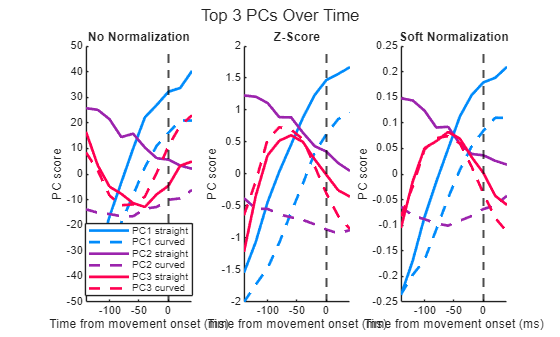


fr_straight = squeeze(mean(firing_rates(1:numel(straight_trials), :, :), 1));  % [n_units x n_bins]
fr_curved   = squeeze(mean(firing_rates(numel(straight_trials)+1:end, :, :), 1));
fr_cond_avg = permute(cat(3, fr_straight', fr_curved'), [3 1 2]);  % [2 x n_bins x n_units]
n_conds = 2;

k = 5;
soft_norm = 5;
methods = {'none', 'zscore', 'soft'};
normalization_labels = {'No Normalization', 'Z-Score', 'Soft Normalization'};
colors_method = [0 0 0; 0 0 1; 1 0 0];

n_straight = numel(straight_trials);
n_curved = numel(curved_trials);
cond_labels = [ones(n_straight, 1); 2*ones(n_curved, 1)];

fold_ids_trials = zeros(n_trials, 1);
for cond = 1:2
    cond_mask = find(cond_labels == cond);
    n_cond = numel(cond_mask);
    perm = randperm(n_cond);
    cond_folds = mod(0:n_cond-1, k) + 1;
    fold_ids_trials(cond_mask) = cond_folds(perm);
end

n_X_fixed = floor(n_units / 2);
max_dims = n_X_fixed - 1;

cv_loss = nan(numel(methods), k, k, max_dims);
n_plot_dims = min(n_X_fixed - 1, 2*n_bins - 1);
all_explained = nan(numel(methods), n_plot_dims);
all_score = cell(numel(methods), 1);
all_coeff = cell(numel(methods), 1);

for m = 1:numel(methods)

    for fold_r = 1:k
        train_idx = find(fold_ids_trials ~= fold_r);
        test_idx = find(fold_ids_trials == fold_r);
        n_train = numel(train_idx);
        n_test = numel(test_idx);

        for fold_c = 1:k
            neuron_perm = randperm(n_units);
            x_neurons = neuron_perm(1:n_X_fixed);
            y_neurons = neuron_perm(n_X_fixed+1:end);
            n_Y = numel(y_neurons);

            X_train = reshape(permute(firing_rates(train_idx, x_neurons, :), [1 3 2]), n_train*n_bins, n_X_fixed);
            Y_train = reshape(permute(firing_rates(train_idx, y_neurons, :), [1 3 2]), n_train*n_bins, n_Y);
            X_test = reshape(permute(firing_rates(test_idx,  x_neurons, :), [1 3 2]), n_test*n_bins,  n_X_fixed);
            Y_test = reshape(permute(firing_rates(test_idx,  y_neurons, :), [1 3 2]), n_test*n_bins,  n_Y);

            switch methods{m}
                case 'none'
                    X_train_n = X_train; X_test_n = X_test;
                case 'zscore'
                    mu_x = mean(X_train, 1);
                    sig_x = std(X_train, 0, 1); sig_x(sig_x==0) = 1;
                    X_train_n = (X_train - mu_x) ./ sig_x;
                    X_test_n  = (X_test  - mu_x) ./ sig_x;
                case 'soft'
                    rng_x = max(X_train,[],1) - min(X_train,[],1);
                    X_train_n = X_train ./ (rng_x + soft_norm);
                    X_test_n  = X_test  ./ (rng_x + soft_norm);
            end

            mu_X = mean(X_train_n, 1);
            X_train_c = X_train_n - mu_X;
            X_test_c = X_test_n  - mu_X;
            mu_Y = mean(Y_train, 1);
            Y_train_c = Y_train - mu_Y;

            [coeff, score, ~] = pca(X_train_c, 'NumComponents', max_dims);

            for d = 1:max_dims
                S_train = score(:, 1:d);
                beta = S_train \ Y_train_c;
                S_test = X_test_c * coeff(:, 1:d);
                Y_hat = S_test * beta + mu_Y;
                cv_loss(m, fold_r, fold_c, d) = mean((Y_test - Y_hat).^2, 'all');
            end
        end
    end

    X_plot = reshape(fr_cond_avg(:, :, :), n_conds*n_bins, n_units);
    FR_all = reshape(permute(firing_rates, [1 3 2]), n_trials*n_bins, n_units);
    
    switch methods{m}
        case 'none'
            FR_all_n = FR_all;
        case 'zscore'
            mu_x = mean(FR_all, 1);
            sig_x = std(FR_all, 0, 1); sig_x(sig_x==0) = 1;
            FR_all_n = (FR_all - mu_x) ./ sig_x;
        case 'soft'
            rng_x = max(FR_all,[],1) - min(FR_all,[],1);
            FR_all_n = FR_all ./ (rng_x + soft_norm);
    end
    
    FR_all_n = reshape(FR_all_n, n_trials, n_bins, n_units);
    psth_s = squeeze(mean(FR_all_n(1:n_straight, :, :), 1)); 
    psth_c = squeeze(mean(FR_all_n(n_straight+1:end, :, :), 1));
    X_plot_final = [psth_s; psth_c];
    X_plot_final = X_plot_final - mean(X_plot_final, 1);
    
    [coeff_full, score_full, ~, ~, explained] = pca(X_plot_final);
    all_score{m} = score_full;  
    all_explained(m, :) = explained(1:n_plot_dims)';
    all_score{m} = score_full;
    all_coeff{m} = coeff_full;
end

mean_loss = squeeze(mean(cv_loss, [2 3]));

% 2D PCA Trajectories
figure;
pc_colors = nebula(3);
for m = 1:numel(methods)
    subplot(1, 3, m); hold on;
    score = all_score{m};
    pc_straight = score(1:n_bins, cv_idx);
    pc_curved = score(n_bins+1:end, cv_idx);
    for pc = 1:3
        plot(bin_centers, score(1:n_bins, pc), '-',  'Color', pc_colors(pc,:), 'LineWidth', 2);
        plot(bin_centers, score(n_bins+1:end, pc), '--', 'Color', pc_colors(pc,:), 'LineWidth', 2);
    end
    xline(0, 'k--', 'LineWidth', 1.5);
    xlabel('Time from movement onset (ms)');
    ylabel('PC score');
    title(normalization_labels{m});
    if m == 1
        legend('PC1 straight','PC1 curved','PC2 straight','PC2 curved', ...
               'PC3 straight','PC3 curved','Location','best');
    end
end
sgtitle('Top 3 PCs Over Time');


% 3D PCA Trajectories

## Helper functions

function ff = compute_fano_factor(counts)
    m  = mean(counts, 1);
    v  = var(counts,  0, 1);
    ff = nan(size(m));
    valid = m > 0;
    ff(valid) = v(valid) ./ m(valid);
end
